clear

figure
shaft = create_primary_shaft();
show(shaft, 'Collisions',"on",'Visuals',"off");
hold on;
draw_walls();
draw_fixed_shaft();

xlim([-1 10])
ylim([-2.5 2.5])
zlim([-4 5])
view([162.62 20.75])

start_pose = [0 0 0 0 0 0];
goal_pose = [2 0 3 0 0 0];

path = rrt(start_pose, goal_pose)

collision_count = 157

path = 1×35 struct array with fields:
    pose
    parent


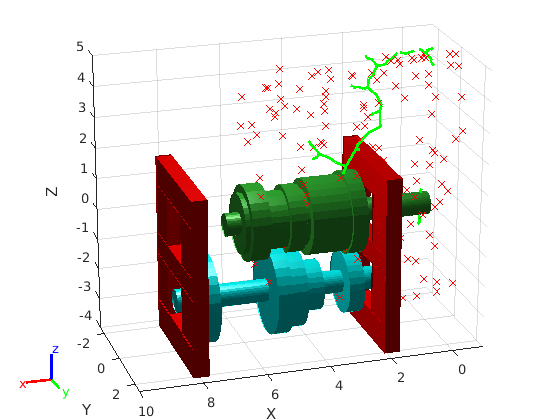


hold off;

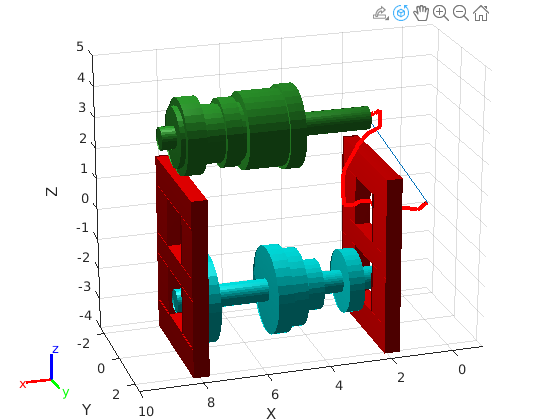

% Now we draw the generated path!
figure
goal_shaft = pose_shaft(goal_pose);
show(goal_shaft, 'Collisions',"on",'Visuals',"off");
xlim([-1 10])
ylim([-2.5 2.5])
zlim([-4 5])
view([162.62 20.75])
hold on;
draw_walls();
draw_fixed_shaft();
draw_path(path);
hold off;

animate_path(path)

path = 1×35 struct array with fields:
    pose
    parent


## Functions

function path = rrt(start, goal)
    start_node = node_from_pose(start);
    goal_node = node_from_pose(goal);
    walls = get_walls();
    fixed_shaft = get_fixed_shaft();

    nodes = [start_node];
    max_nodes = 2000;
    incremental_step = 0.1;

    collision_count = 0;

    for i=1:max_nodes
        % Chance of a random pose or a goal pose
        if mod(i,10)==0
            random_pose=goal;
        else
            random_pose = get_random_pose();
        end
        random_node = node_from_pose(random_pose);

        % Draw the node in 3d space
        draw_pose = random_pose(1,1:3);
        plot3(draw_pose(1), draw_pose(2), draw_pose(3), ...
            'x', 'Color', 'red');
        
        % Grab the nearest node to our random point
        % to branch from
        nearest_node = get_closest_node(random_node, nodes);
        
        % Move the transmission a controlled step in
        % that direction
        new_node = step(nearest_node, random_node, incremental_step);

        % Ensure that the 3d pose generated is possible
        % and does not create collisions
        tmp_shaft = pose_shaft(new_node.pose);
        collides = check_collisions(tmp_shaft, fixed_shaft, walls);
        if collides == 1
            collision_count = collision_count+ 1;
            continue
        end

        draw_pose_a = nearest_node.pose(1,1:3);
        draw_pose_b = new_node.pose(1,1:3);
        line(...
            [draw_pose_a(1), draw_pose_b(1)], ...
            [draw_pose_a(2), draw_pose_b(2)], ...
            [draw_pose_a(3), draw_pose_b(3)], ...
            'Color', 'green', 'LineWidth', 2);
        drawnow;

        % Append to our nodelist and move on!
        nodes(end+1) = new_node;

        % If our new node is the goal, we can break!
        if distance_between(new_node, goal_node) < 0.1
            goal_node.parent = new_node;
            break;
        end

    end

    collision_count

    if ~isstruct(goal_node.parent)
        path = [];
        return
    end

    path(1) = goal_node;
    parent = goal_node.parent;
    while isstruct(parent)
        path(end+1) = parent;
        parent = parent.parent;
    end
    path = flip(path);
    return
end

function new_node = step(start, towards, incremental_step)
    distance = distance_between(start, towards);
    new_node = struct("pose", [0 0 0], "parent", start);

    if distance <= 0.1
        new_node = towards;
        new_node.parent = start;
    else
        towards_diff = towards.pose - start.pose;
        new_node.pose(1) = start.pose(1) + (towards_diff(1)*incremental_step);
        new_node.pose(2) = start.pose(2) + (towards_diff(2)*incremental_step);
        new_node.pose(3) = start.pose(3) + (towards_diff(3)*incremental_step);
        new_node.pose(4) = start.pose(4) + (towards_diff(4)*incremental_step);
        new_node.pose(5) = start.pose(5) + (towards_diff(5)*incremental_step);
        new_node.pose(6) = start.pose(6) + (towards_diff(6)*incremental_step);
    end
end

function shaft = pose_shaft(pose)
    shaft = create_primary_shaft();
    new_tree = rigidBodyTree("DataFormat", "column");
    rigid_body = rigidBody("new_base");
    transform = trvec2tform([pose(1), pose(2), pose(3)]) * ...
        axang2tform([1 0 0 pose(4)]) * axang2tform([0 1 0 pose(5)]) * ...
        axang2tform([0 0 1 pose(6)]);
    rigid_body.Joint.setFixedTransform(transform);
    new_tree.addBody(rigid_body, 'base');
    tmp_tree = removeBody(shaft, "cylinder_1");
    new_tree.addSubtree('new_base', tmp_tree);

    shaft = new_tree;
end

function node = node_from_pose(pose)
    node = struct("pose", pose, "parent", -1);
end

function value = random(min, max)
    value = min + (max-min)*rand(1);
end

function random_pose = get_random_pose()
    x_min = -2; 
    x_max = 6;
    y_min = -1;
    y_max = 1;
    z_min = -3;
    z_max = 8;
    roll_min = 0;
    roll_max = 0;
    pitch_min = -pi/2;
    pitch_max = 3*pi/4;
    yaw_min = 0;
    yaw_max = 0;

   random_pose = [random(x_min, x_max), ...
       random(y_min, y_max), random(z_min, z_max), ...
       random(roll_min, roll_max), random(pitch_min, pitch_max), ...
       random(yaw_min, yaw_max)];
end

function closest_node = get_closest_node(node, node_list)
    distances = [];
    for i = 1:1:length(node_list)
        considered_node = node_list(i);
        distance = distance_between(node, considered_node);
        distances = [distances distance];
    end
    [distance, index] = min(distances);
    closest_node = node_list(index);
end

function distance = distance_between(node_a, node_b)
    distance = sqrt( ...
        (node_a.pose(1)-node_b.pose(1))^2+...
        (node_a.pose(2)-node_b.pose(2))^2+...
        (node_a.pose(3)-node_b.pose(3))^2 ...
        );
end

function counter_shaft = get_fixed_shaft()
    cylinders ={
        struct("length", 0.76, "radius", 0.36, "translation", [.38+1.6; 0; -2.31;]),
        struct("length", 0.5, "radius", 1, "translation", [1.01+1.6; 0; -2.31;]),
        struct("length", 0.76, "radius", 0.36, "translation", [1.64+1.6; 0; -2.31;]),
        struct("length", 0.5, "radius", 0.8, "translation", [2.27+1.6; 0; -2.31;]),
        struct("length", 0.16, "radius", 0.36, "translation", [2.6+1.6; 0; -2.31;]),
        struct("length", 0.5, "radius", 1.235, "translation", [2.91+1.6; 0; -2.31;]),
        struct("length", 0.5, "radius", 1.395, "translation", [3.43+1.6; 0; -2.31;]),
        struct("length", 1.82, "radius", 0.36, "translation", [4.59+1.6; 0; -2.31;]),
        struct("length", 0.5, "radius", 1.40, "translation", [5.75+1.6; 0; -2.31]),
        struct("length", 0.6, "radius", 0.36, "translation", [6.3+1.6; 0; -2.31;]),
    };

    counter_shaft = {};
    
    for i=1:length(cylinders)
        part = cylinders{i};
    
        len = part.length;
        radius = part.radius;
    
        cylinder = collisionCylinder(radius, len);
        axis = [0 1 0 pi/2];
        transformation = axang2tform(axis);
        transformation(1:3, 4) = part.translation;
        cylinder.Pose = transformation;
        counter_shaft{end+1} = cylinder;
    end
end

function walls = get_walls()
    right_wall = {
        struct("x", .5, "y", 4.2, "z", 1.7, "origin", [.25+1.6; 0; -3.95]),
        struct("x", .5, "y", 1.3, "z", 1.6, "origin", [.25+1.6; 1.45; -2.3]),
        struct("x", .5, "y", 1.3, "z", 1.6, "origin", [.25+1.6; -1.45; -2.3]),
        struct("x", .5, "y", 4.2, "z", 0.7, "origin", [.25+1.6; 0; -1.15]),
        struct("x", .5, "y", 1.3, "z", 1.6, "origin", [.25+1.6; 1.45; 0]),
        struct("x", .5, "y", 1.3, "z", 1.6, "origin", [.25+1.6; -1.45; 0]),
        struct("x", .5, "y", 4.2, "z", 0.9, "origin", [.25+1.6; 0; 1.25]),
    };
    left_wall = {
        struct("x", .5, "y", 4.2, "z", 1.7, "origin", [6.35+1.6; 0; -3.9]),
        struct("x", .5, "y", 1.3, "z", 1.6, "origin", [6.35+1.6; 1.45; -2.3]),
        struct("x", .5, "y", 1.3, "z", 1.6, "origin", [6.35+1.6; -1.45; -2.3]),
        struct("x", .5, "y", 4.2, "z", 0.7, "origin", [6.35+1.6; 0; -1.15]),
        struct("x", .5, "y", 1.3, "z", 1.6, "origin", [6.35+1.6; 1.45; 0]),
        struct("x", .5, "y", 1.3, "z", 1.6, "origin", [6.35+1.6; -1.45; 0]),
        struct("x", .5, "y", 4.2, "z", 0.9, "origin", [6.35+1.6; 0; 1.25]),
    };
    boxes = [left_wall; right_wall;];

    walls = {};
    
    for i=1:length(boxes)
        wall = boxes{i};
        box = collisionBox(wall.x, wall.y, wall.z);
        transformation = [eye(3) wall.origin; 0 0 0 1];
        box.Pose = transformation;
        walls{end+1} = box;
    end
end

function draw_shaft(shaft, color)
    for i=1:length(shaft)
        cylinder = shaft{i};
        [~, patch_object] = show(cylinder);
        patch_object.FaceColor = color;
        patch_object.EdgeColor = 'none';
    end
end

function draw_fixed_shaft()
    shaft = get_fixed_shaft();
    draw_shaft(shaft, [0 1 1]);
end

function draw_walls()
    walls = get_walls();
    for i=1:length(walls)
        box = walls{i};
        [~, patch_object] = show(box);
        patch_object.FaceColor = [1 0 0];
        patch_object.EdgeColor = 'none';
    end
end

function shaft = create_primary_shaft()
    primary_shaft ={
        struct("length", 6.6, "radius", .36, "translation", [1.5; 0; 4.9]),
        struct("length", .5, "radius", 1.3, "translation", [1.01; 0; 4.9]),
        struct("length", 1.25, "radius", 1.2, "translation", [1.635; 0; 4.9]),
        struct("length", .16, "radius", .9, "translation", [2.59; 0; 4.9]),
        struct("length", .5, "radius", 1.06, "translation", [2.92; 0; 4.9]),
        struct("length", .65, "radius", .9, "translation", [3.495; 0; 4.9]),
        struct("length", .6, "radius", 1.195, "translation", [4.12; 0; 4.9]),
        struct("length", .16, "radius", .95, "translation", [4.5; 0; 4.9]),
    };

    dh_params=[0 0 0 pi/2;
                 2.36 0 0 0;
                 .5 0 0 0;
                 1.25 0 0 0;
                 .16 0 0 0;
                 .5 0 0 0;
                 .65 0 0 0;
                 .6 0 0 0;
                 .16 0 0 0];

    shaft = create_shaft(primary_shaft, dh_params);
end

function shaft = create_shaft(collision_geometries, dh_params)
    shaft = rigidBodyTree("DataFormat", "column");
    basename=shaft.BaseName;
    
    cylinder_1 = rigidBody('cylinder_1');
    cylinder_2 = rigidBody('cylinder_2');
    cylinder_3 = rigidBody('cylinder_3');
    cylinder_4 = rigidBody('cylinder_4');
    cylinder_5 = rigidBody('cylinder_5');
    cylinder_6 = rigidBody('cylinder_6');
    cylinder_7 = rigidBody('cylinder_7');
    cylinder_8 = rigidBody('cylinder_8');
    
    joint_1 = rigidBodyJoint('joint_1','revolute');
    joint_1.JointAxis=[0,1,0];
    cylinder_1.Joint=joint_1;
    setFixedTransform(joint_1,dh_params(1,:),'dh');
    
    joint_2 = rigidBodyJoint('joint_2','fixed');
    setFixedTransform(joint_2,dh_params(2,:),'dh');
    cylinder_2.Joint=joint_2;
    
    joint_3 = rigidBodyJoint('joint_3','fixed');
    setFixedTransform(joint_3,dh_params(3,:),'dh');
    cylinder_3.Joint=joint_3;
    
    joint_4 = rigidBodyJoint('joint_4','fixed');
    setFixedTransform(joint_4,dh_params(4,:),'dh');
    cylinder_4.Joint=joint_4;
    
    joint_5 = rigidBodyJoint('joint_5','fixed');
    setFixedTransform(joint_5,dh_params(5,:),'dh');
    cylinder_5.Joint=joint_5;
    
    joint_6 = rigidBodyJoint('joint_6','fixed');
    setFixedTransform(joint_6,dh_params(6,:),'dh');
    cylinder_6.Joint=joint_6;
    
    joint_7 = rigidBodyJoint('joint_7','fixed');
    setFixedTransform(joint_7,dh_params(7,:),'dh');
    cylinder_7.Joint=joint_7;
    
    joint_8 = rigidBodyJoint('joint_8','fixed');
    setFixedTransform(joint_8,dh_params(8,:),'dh');
    cylinder_8.Joint=joint_8;
    
    addBody(shaft, cylinder_1, basename);
    addBody(shaft, cylinder_2, 'cylinder_1');
    addBody(shaft, cylinder_3, 'cylinder_2');
    addBody(shaft, cylinder_4, 'cylinder_3');
    addBody(shaft, cylinder_5, 'cylinder_4');
    addBody(shaft, cylinder_6, 'cylinder_5');
    addBody(shaft, cylinder_7, 'cylinder_6');
    addBody(shaft, cylinder_8, 'cylinder_7');
    

    for i=1:length(collision_geometries)
        cylinder = collision_geometries{i};
        collision_cylinder = collisionCylinder(cylinder.radius, cylinder.length);
        axis = [0 1 0 pi/2];
        transformation = trvec2tform([cylinder.length/2,0,0])*axang2tform(axis);
        collision_cylinder.Pose = transformation;
        addCollision(shaft.Bodies{i}, collision_cylinder);
    end
    
end

function collides = check_collisions(shaft, fixed_shaft, walls)
    collides = 0;
    home_config = homeConfiguration(shaft);
    collisions = checkCollision(shaft, home_config, walls);
    if collisions(2) == 1
        collides = 1;
        return
    end
    collisions = checkCollision(shaft, home_config, fixed_shaft);
    if collisions(2) == 1
        collides = 1;
        return
    end
end

function draw_path(path)
    while length(path) > 1
        start = path(1);
        next = path(2);
        path = path(2:end);

        start_xyz = start.pose(1:3);
        next_xyz = next.pose(1:3);
        line(...
            [start_xyz(1), next_xyz(1)], ...
            [start_xyz(2), next_xyz(2)], ...
            [start_xyz(3), next_xyz(3)], ...
            'Color', 'red', 'LineWidth', 3);
    end
end

function animate_path(path)
    animated=figure;
    gif('path.gif');
    for i=1:length(path)
        shaft = pose_shaft(path(i).pose);
        config = homeConfiguration(shaft);
        show(shaft,'Collisions',"on",'Visuals',"off");
        hold on;
        draw_walls();
        draw_fixed_shaft();
        
        xlim([-1 10])
        ylim([-2.5 2.5])
        zlim([-4 5])
        view([162.62 20.75])
        
        gif
        hold off;
    end
end

% gif function by Chad Greene
function gif(varargin)
% gif is the simplest way to make gifs. Simply call
% 
%   gif('myfile.gif') 
% 
% to write the first frame, and then call 
% 
%   gif
% 
% to write each subsequent frame. That's it. 
% 
%% Syntax
% 
%  gif('filename.gif') 
%  gif(...,'DelayTime',DelayTimeValue,...) 
%  gif(...,'LoopCount',LoopCountValue,...) 
%  gif(...,'frame',handle,...) 
%  gif(...,'resolution',res)
%  gif(...,'nodither') 
%  gif(...,'overwrite',true)
%  gif 
%  gif('clear') 
% 
%% Description 
% 
% gif('filename.gif') writes the first frame of a new gif file by the name filename.gif. 
% 
% gif(...,'DelayTime',DelayTimeValue,...) specifies a the delay time in seconds between
% frames. Default delay time is 1/15. 
% 
% gif(...,'LoopCount',LoopCountValue,...) specifies the number of times the gif animation 
% will play. Default loop count is Inf. 
% 
% gif(...,'frame',handle,...) uses the frame of the given figure or set of axes. The default 
% frame handle is gcf, meaning the current figure. To turn just one set of axes into a gif, 
% use 'frame',gca. This behavior changed in Jan 2021, as the default option changed from
% gca to gcf.
% 
% gif(...,'resolution',res) specifies the resolution (in dpi) of each frame. This option
% requires export_fig (https://www.mathworks.com/matlabcentral/fileexchange/23629).
%
% gif(...,'nodither') maps each color in the original image to the closest color in the new 
% without dithering. Dithering is performed by default to achieve better color resolution, 
% albeit at the expense of spatial resolution.
% 
% gif(...,'overwrite',true) bypasses a dialoge box that would otherwise verify 
% that you want to overwrite an existing file by the specified name. 
%
% gif adds a frame to the current gif file. 
% 
% gif('clear') clears the persistent variables associated with the most recent gif. 
% 
%% Example 
% For examples, type 
% 
%   cdt gif
% 
%% Author Information 
% This function was written by Chad A. Greene of the University of Texas 
% Institute for Geophysics (UTIG), June 2017. 
% 
% See also: imwrite, getframe, and rgb2ind. 
% Define persistent variables: 
persistent gif_filename firstframe DelayTime DitherOption LoopCount frame resolution
%% Parse Inputs
if nargin>0 
   
   % The user may want to clear things and start over: 
   if any(strcmpi(varargin,'clear'))
            
      % Clear persistent variables associated with this function: 
      clear gif_filename firstframe DelayTime DitherOption LoopCount frame resolution
   end
   
   % If the first input ends in .gif, assume this is the first frame:
   if strcmpi(varargin{1}(end-3:end),'.gif')
      
      % This is what the user wants to call the new .gif file: 
      gif_filename = varargin{1}; 
      
      % Check for an existing .gif file by the same name: 
      if exist(gif_filename,'file')==2
         OverWrite = false; % By default, do NOT overwrite an existing file by the input name. 
         if nargin>1
            tmp = strncmpi(varargin,'overwrite',4); 
            if any(tmp)
               OverWrite = varargin{find(tmp)+1}; 
               assert(islogical(OverWrite),'Error: Overwrite input must be either true or false.')
            end
         end
         
         if ~OverWrite
         
            % Ask the user if (s)he wants to overwrite the existing file: 
            choice = questdlg(['The file  ',gif_filename,' already exists. Overwrite it?'], ...
               'The file already exists.','Overwrite','Cancel','Cancel');
            if strcmp(choice,'Overwrite')
               OverWrite = true; 
            end
         end
         
         % Overwriting basically means deleting and starting from scratch: 
         if OverWrite
            delete(gif_filename) 
         else 
            clear gif_filename firstframe DelayTime DitherOption LoopCount frame
            error('The giffing has been canceled.') 
         end
         
      end
      
      firstframe = true; 
      
      % Set defaults: 
      DelayTime = 1/15; 
      DitherOption = 'dither'; 
      LoopCount = Inf; 
      frame = gcf; 
      resolution = 0; % When 0, it's used as a boolean to say "don't use export_fig". If greater than zero, the boolean says "use export_fig and use the specified resolution."  
   end
   
   tmp = strcmpi(varargin,'DelayTime'); 
   if any(tmp) 
      DelayTime = varargin{find(tmp)+1}; 
      assert(isscalar(DelayTime),'Error: DelayTime must be a scalar value.') 
   end
   
   if any(strcmpi(varargin,'nodither'))
      DitherOption = 'nodither'; 
   end
   
   tmp = strcmpi(varargin,'LoopCount'); 
   if any(tmp) 
      LoopCount = varargin{find(tmp)+1}; 
      assert(isscalar(LoopCount),'Error: LoopCount must be a scalar value.') 
   end
   
   tmp = strncmpi(varargin,'resolution',3); 
   if any(tmp) 
      resolution = varargin{find(tmp)+1}; 
      assert(isscalar(resolution),'Error: resolution must be a scalar value.') 
      assert(exist('export_fig.m','file')==2,'export_fig not found. If you wish to specify the image resolution, get export_fig here :https://www.mathworks.com/matlabcentral/fileexchange/23629. Otherwise remove the resolution from the gif inputs to use the default (lower quality) built-in getframe functionality.')  
      warning off export_fig:exportgraphics
   end
   
   tmp = strcmpi(varargin,'frame'); 
   if any(tmp) 
      frame = varargin{find(tmp)+1}; 
      assert(ishandle(frame)==1,'Error: frame must be a figure handle or axis handle.') 
   end
   
else
   assert(isempty(gif_filename)==0,'Error: The first call of the gif function requires a filename ending in .gif.') 
end
%% Perform work: 
if resolution % If resolution is >0, it means use export_fig
   
   if isgraphics(frame,'figure')
      f = export_fig('-nocrop',['-r',num2str(resolution)]);
   else
      % If the frame is a set of axes instead of a figure, use default cropping: 
      f = export_fig(['-r',num2str(resolution)]);
   end
      
else
   % Get frame: 
   fr = getframe(frame); 
   f =  fr.cdata; 
end
% Convert the frame to a colormap and corresponding indices: 
[imind,cmap] = rgb2ind(f,256,DitherOption);    
% Write the file:     
if firstframe
   imwrite(imind,cmap,gif_filename,'gif','LoopCount',LoopCount,'DelayTime',DelayTime)
   firstframe = false;
else
   imwrite(imind,cmap,gif_filename,'gif','WriteMode','append','DelayTime',DelayTime)
end
end